## Set 1: Kinematics (15 pts)

For this set, to receive credits for normal mode, you must do easy mode as well.

Given a 3-DOF Robot Manipulator 

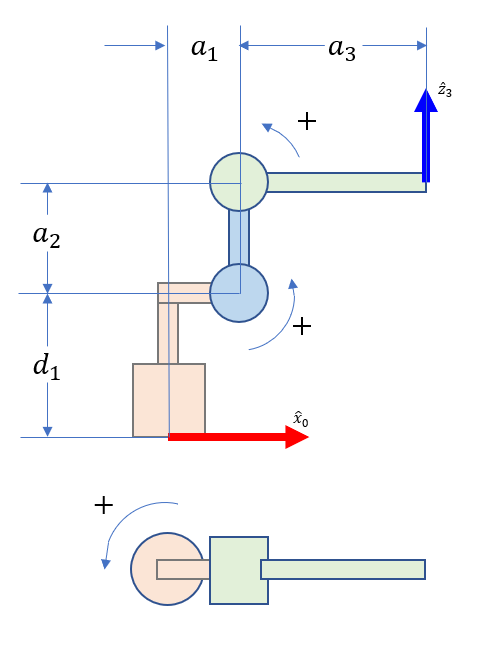

Figure 1: 3DOF Robot at Home Configuration

Easy Mode: (5 Points) 

- All neccesary coordinate frames

- DH Parameters in term of $a_1 ,a_2 ,a_3 ,d_1$

- Forward Kinematics Equation of every frames

- Inverse Kinematics of the end-effector

- Manipulator Jacobian of all frames

Implement 1-5 in MATLAB code. You may use the code from previous homeworks. Regardless, you must explain the workflow in detail.

Use the following parameters for the code.

Normal Mode: (10 Points) 

Show how to compute (1-5) by hand in MATLAB livescript and verify your result with MATLAB. To receive full credits, the result must match. 

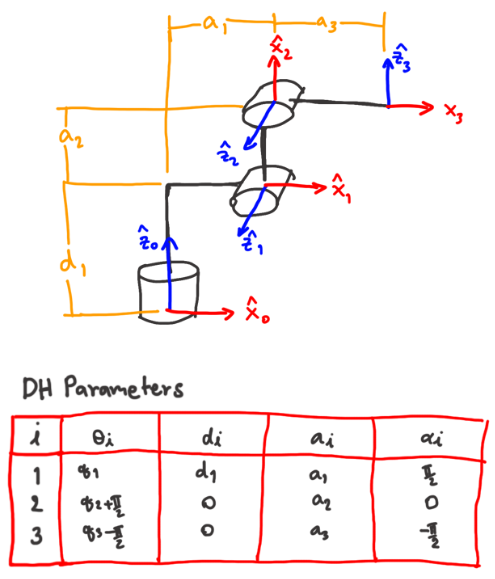

To more easily compare with written answers, we'll substitute in the values at the end.

syms q1 q2 q3 pi a_1 a_2 a_3 d_1
%a_1 = 0.2;
%a_2 = 0.75;
%a_3 = 0.6;
%d_1 = 0.9;
q=[q1 q2 q3];
dh=[0 d_1 a_1 pi/2;pi/2 0 a_2 0;-pi/2 0 a_3 -pi/2];
rho=[1 1 1];

we use the given forwardKinematicsSym function to get the forward kinematics, which creates transforms in the following code snippet and multiply them together successively

FK = forwardKinematicsSym(q,rho,dh)

$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & d_{1}+a_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}-a_{2}\,\sin\left(q_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & d_{1}+a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{1}+a_{3}\,\cos\left(q_{2}+q_{3}\right)-a_{2}\,\sin\left(q_{2}\right) \end{array}$$

**Inverse Kinematics**

We use the an analytical approach to solve by hand, then implemented it as a function

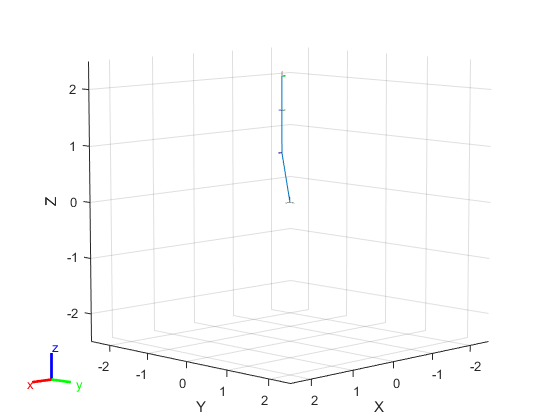

clear

a_1 = 0.2;
a_2 = 0.75;
a_3 = 0.6;
d_1 = 0.9;

dh=[0 d_1 a_1 pi/2;pi/2 0 a_2 0;-pi/2 0 a_3 -pi/2];
rho=[1 1 1];
q = [0;0;0];
[tforms,robot,~] = forwardKinematicsRST(q, rho, dh);
q_test = [0;0;0];
config = homeConfiguration(robot);
for i = numel(q)
    config(i).JointPosition = q_test(i);
end
show(robot, config);

transform = getTransform(robot, config, "link_3");
p = tforms(1:3,4, 3)

p =     0.8000
    0.0000
    1.6500


q_solution = analyticalIK(p)

q_solution =     0.0000    0.0000
   -0.0000   -1.3495
         0    3.1416


q = sym('q_',[3,1]);
assume(q,'real');
syms pi a_1 a_2 a_3 d_1
dh=[0 d_1 a_1 pi/2;pi/2 0 a_2 0;-pi/2 0 a_3 -pi/2];
rho=[1 1 1];

J = manipulatorJacobianSym(q,rho,dh)

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0\\ -a_{1}\,\sin\left(q_{1}\right) & 0 & 0\\ a_{1}\,\cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} 0 & \sin\left(q_{1}\right) & 0\\ 0 & -\cos\left(q_{1}\right) & 0\\ 1 & 0 & 0\\ -\sin\left(q_{1}\right)\,\left(a_{1}-a_{2}\,\sin\left(q_{2}\right)\right) & -a_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & 0\\ \cos\left(q_{1}\right)\,\left(a_{1}-a_{2}\,\sin\left(q_{2}\right)\right) & -a_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & 0\\ 0 & -a_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{ccc} 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\\ 1 & 0 & 0\\ -\sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{3}-a_{2}\,\sin\left(q_{2}\right) & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=a_{1}+\sigma_{3}-a_{2}\,\sin\left(q_{2}\right)\\ \sigma_{3}=a_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

tform = forwardKinematicsSym(q,rho,dh);
p_e = tform(1:3,4,end);

% must return 0 for both
simplify(jacobian(p_e,q)-J(4:6,:,end))  

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

.

We use the pseudocode found in the lecture slide to find each Jacobian for each joint

Then wrap it with a for loop iterating for each joint as an endpoint